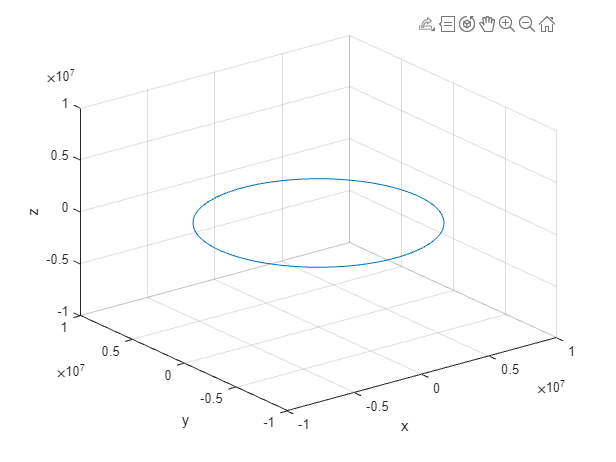

opts = delimitedTextImportOptions("NumVariables", 3);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["x", "y", "z"];
opts.VariableTypes = ["double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
output = readtable("\\wsl.localhost\ubuntu\home\joseph\code\rbody\output.txt", opts);
x = output.x;
y = output.y;
z = output.z;
clear opts output

plot3(x,y,z)
xlabel("x"),ylabel("y"),zlabel("z")
xlim([-10000e3,10000e3])
ylim([-10000e3,10000e3])
zlim([-10000e3,10000e3])
grid on


% axis("equal")
% axis("square")